# Collaborate@ICERM 2026

## Extending permeable walls of channel -- Stokeslets Only

Tests to run:

Non-permeable (solid) walls, stokeslets only:

- Compute velocities as usual

- Compute pressures as usual

- Extend wall boundary (keep inlet/outlet same location) and compute velocities

- Extend wall boundary (keep inlet/outlet same location) and compute pressures

- Compute pressure using Gauss' law approach and compare to other pressure computation

## Permeable wall computation without extended boundary (Stokeslets Only)

clear
close all 

#### **Set parameters**

- Blob choice 2 uses $\psi$ from 2021 paper

- Blob choice 1 uses $\phi$ from 2021 paper

%set Darcy number
Da = 0.4;
%viscosity
mu = 1; 
%choose blob
blob_num = 2;
% scale factor for epsilon*ds_y
epsilon_factor = 1; % sqrt(5)/2

% Number of source and target points
N = 160; % Number of source points (along top  and bottom boundaries)
Nx2 = 80; % Number of target points in y direction for full channel calc
Nx1 = floor(pi*Nx2); % Number of target points in x direction for full channel calc

#### **Define geometry and regularization**

% Setting forces and computing velocity 
% Channel geometry
Lx = pi;
Ly = 1;
xmin = -Lx;
xmax = Lx;
ymin = -Ly;
ymax = Ly;

scalefactor = 0.05; % for the boundary velocity figures (why?)

% Discretization step
ds_x = (xmax - xmin)/(N-1);
ds_y = (ymax - ymin)/( ceil((ymax - ymin)/ds_x));

%regularization parameter
ep = epsilon_factor*ds_y;

#### **Discretization**

tb = top/bottom

lr = left/right

source point coordinates organized stacked:

    [top; bottom; left; right]

%discretization step of top/bottom walls
stb = xmin+ds_x/2:ds_x:xmax-ds_x/2;
stb = stb';
%discretization step of left/right wall (inlet/outlet)
slr = ymin+ds_y/2:ds_y:ymax-ds_y/2;
slr = slr';

% Define coordinates on each wall (x-coord,y-coord) (source points)
y1_top = stb;   y2_top = ymax*ones(size(stb)); % top wall coordinates (y1_top,y2_top)
y1_bot = stb;   y2_bot = ymin*ones(size(stb)); % bottom wall coordinates (y1_bot,y2_bot)
y1_left = xmin*ones(size(slr));   y2_left = slr; % left wall coordinates (y1_left,y2_left)
y1_right = xmax*ones(size(slr));   y2_right = slr; % right wall coordinates (y1_right,y2_right)
y1 = [y1_top; y1_bot; y1_left; y1_right]; %x-coordinates of all boundary points
y2 = [y2_top; y2_bot; y2_left; y2_right]; %y-coordinates of all boundary points

% Points where velocity will be computed within the channel (target points)
%xx1 = [xmin, stb', xmax]; % include boundary points in error computation
%xx2 = [ymin, slr', ymax]; % include boundary points in error computation
xx1 = stb';
xx2 = slr';
[x1m, x2m] = ndgrid(xx1, xx2);
x1 = x1m(:); %x-coords of points where computing velocity
x2 = x2m(:); %y-coords of points where computing velocity
dx_g = (xx1(end)-xx1(1))/Nx1;
dy_g = (xx2(end)-xx2(1))/Nx2;

#### **Set boundary velocities and beta**

% Define quadrature weights cooresponding to wall coordinates.
% Currently using midpoint rule.
wt = [ds_x*ones(size(y1_top)); ds_x*ones(size(y1_bot)); ds_y*ones(size(y1_left)); ds_y*ones(size(y1_right))];

% Exact velocities on boundaries using true solution (Bernardi, 2023)
[u1_top_exact,u2_top_exact,p_top_exact] = permeablechannelexact(y1_top,y2_top,Da); %top velocity
[u1_bot_exact,u2_bot_exact,p_bot_exact] = permeablechannelexact(y1_bot,y2_bot,Da); %bottom velocity
[u1_left_exact,u2_left_exact,p_left_exact] = permeablechannelexact(y1_left,y2_left,Da); % left velocity
[u1_right_exact,u2_right_exact,p_right_exact] = permeablechannelexact(y1_right,y2_right,Da); %right velocity

u1_bd_exact = [u1_top_exact; u1_bot_exact; u1_left_exact; u1_right_exact]; %x-coordinates of all boundary velocities
u2_bd_exact  = [u2_top_exact; u2_bot_exact; u2_left_exact; u2_right_exact]; %y-coordinates of all boundary velocities
p_bd_exact = [p_top_exact; p_bot_exact; p_left_exact; p_right_exact]; % pressure on boundary

u1_tb_exact = [u1_top_exact; u1_bot_exact];
u2_tb_exact = [u2_top_exact; u2_bot_exact];
p_tb_exact = [p_top_exact; p_bot_exact];

#### **Find forces on boundary due to known velocities**

% All four sides of channel
ftemp = RegStokeslets2D_velocitytoforce_KK([y1,y2], [y1,y2], [u1_bd_exact,u2_bd_exact], ep, mu, blob_num,wt);

log10 of condition number of Mat: 3.506
condition number of Mat+D: 3138.637
size of Mat+D: 840  840


#### **Compute velocity and pressure everywhere due to boundary forces**

ug = RegStokeslets2D_forcetovelocity([y1,y2],ftemp,[x1,x2],ep,mu,blob_num,wt);
ug1 = ug(:,1);
ug2 = ug(:,2);
u1m = reshape(ug1,size(xx1,2),size(xx2,2)); % x-coords of computed velocities everywhere
u2m = reshape(ug2,size(xx1,2),size(xx2,2)); % y-coords of computed velocities everywhere
ummag = sqrt(u1m.^2 + u2m.^2);

% computed pressure
p = RegStokeslets2D_forcetopressure([y1, y2], ftemp, [x1, x2], ep, mu, blob_num, wt);
pm = reshape(p,size(xx1,2),size(xx2,2));

### Plotting

#### Streamlines of Exact and Computed 

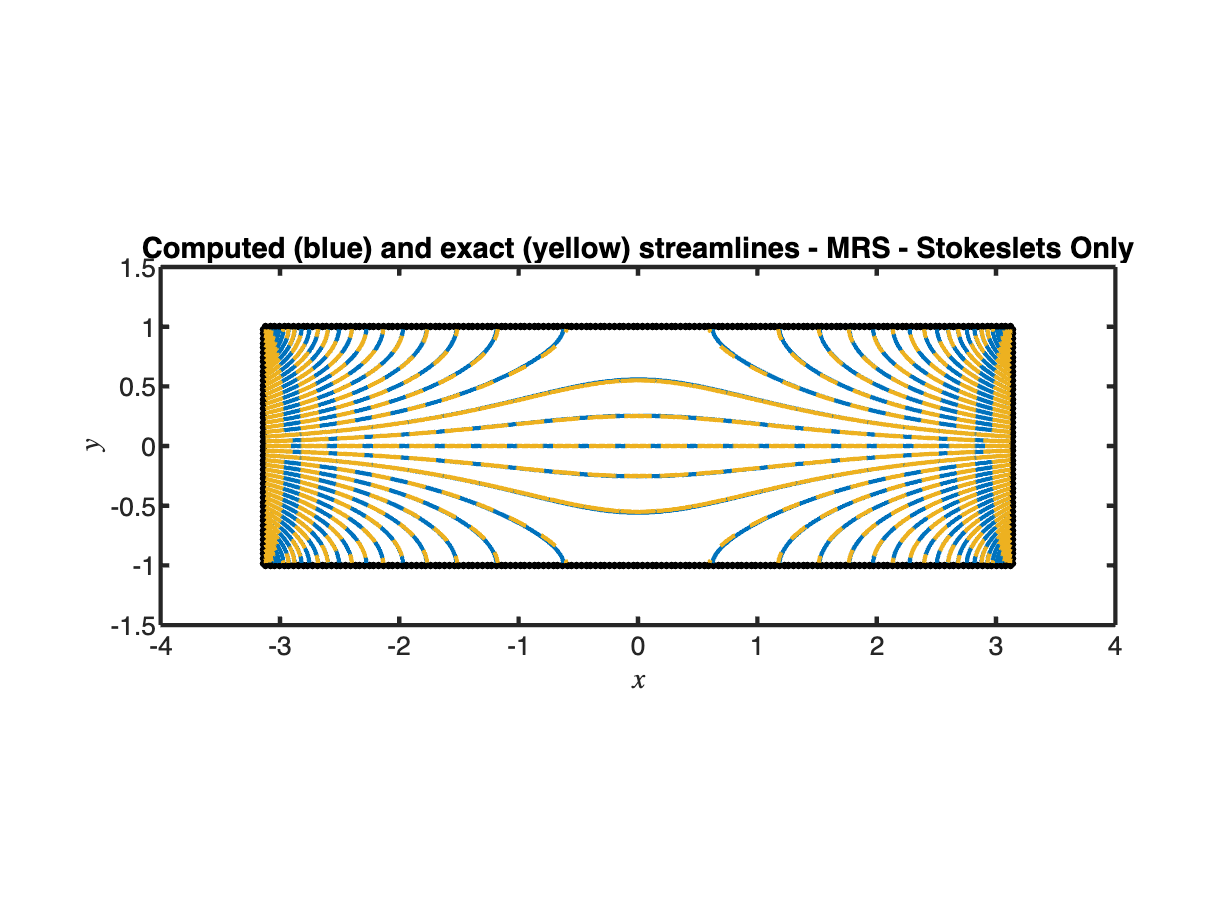

[x1gg, x2gg] = meshgrid(xx1, xx2);
[uexact,vexact,~] = permeablechannelexact(x1gg,x2gg,Da);
speed_exact = sqrt(uexact.^2 + vexact.^2);

figure
plot_streamline(u1m,u2m,x1gg,x2gg,uexact,vexact,y1,y2,'MRS - Stokeslets Only')

#### Quiver plot of exact velocities on boundaries

subplot(2,1,1)
plot_boundary_quiver(y1, y2, x1m, x2m, u1_bd_exact, u2_bd_exact, u1m, u2m)

#### pcolor plot of velocities everywhere with quiver of computed forces on boundaries

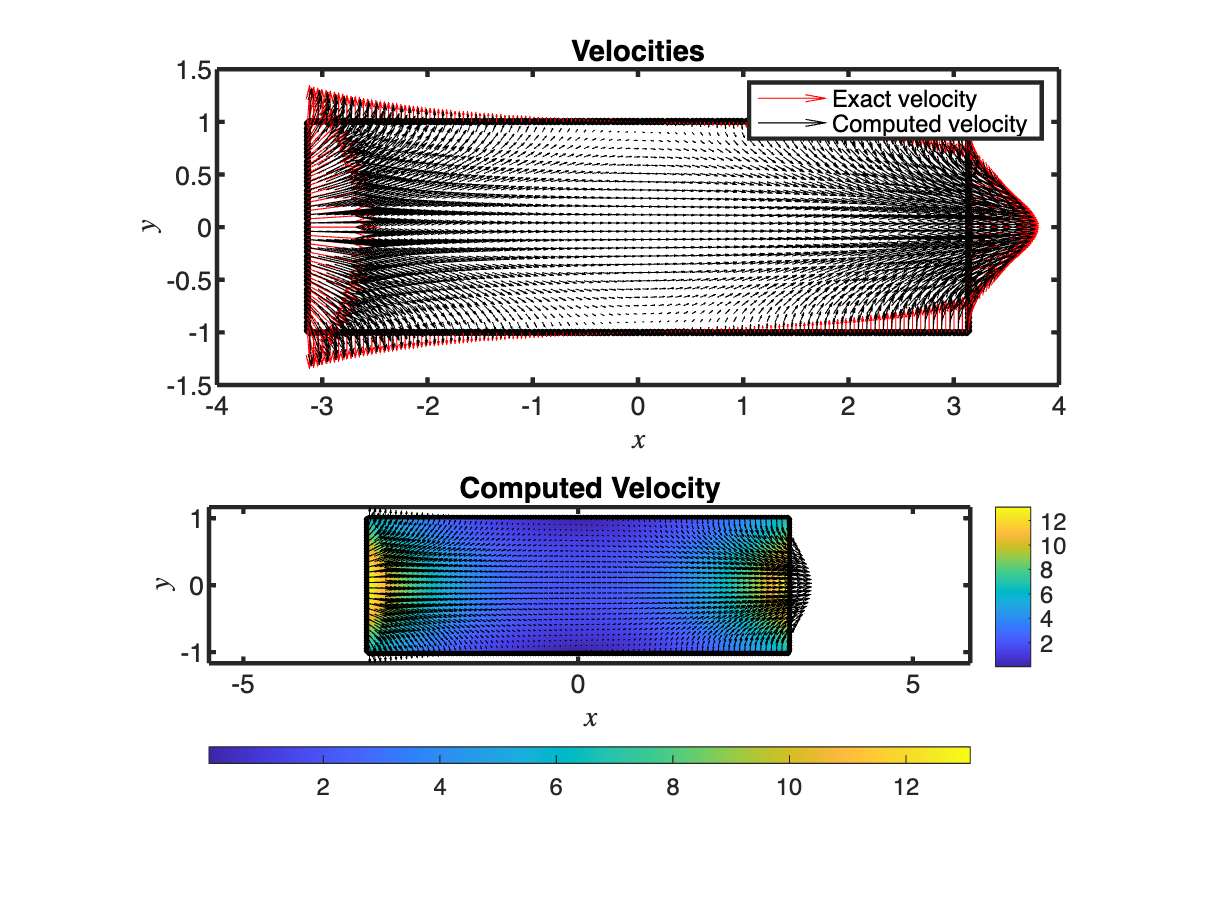

subplot(2,1,2)
plot_velocity_pcolor(y1,y2,x1m,x2m,u1m,u2m,ummag)

#### Calculate Errors and Plot

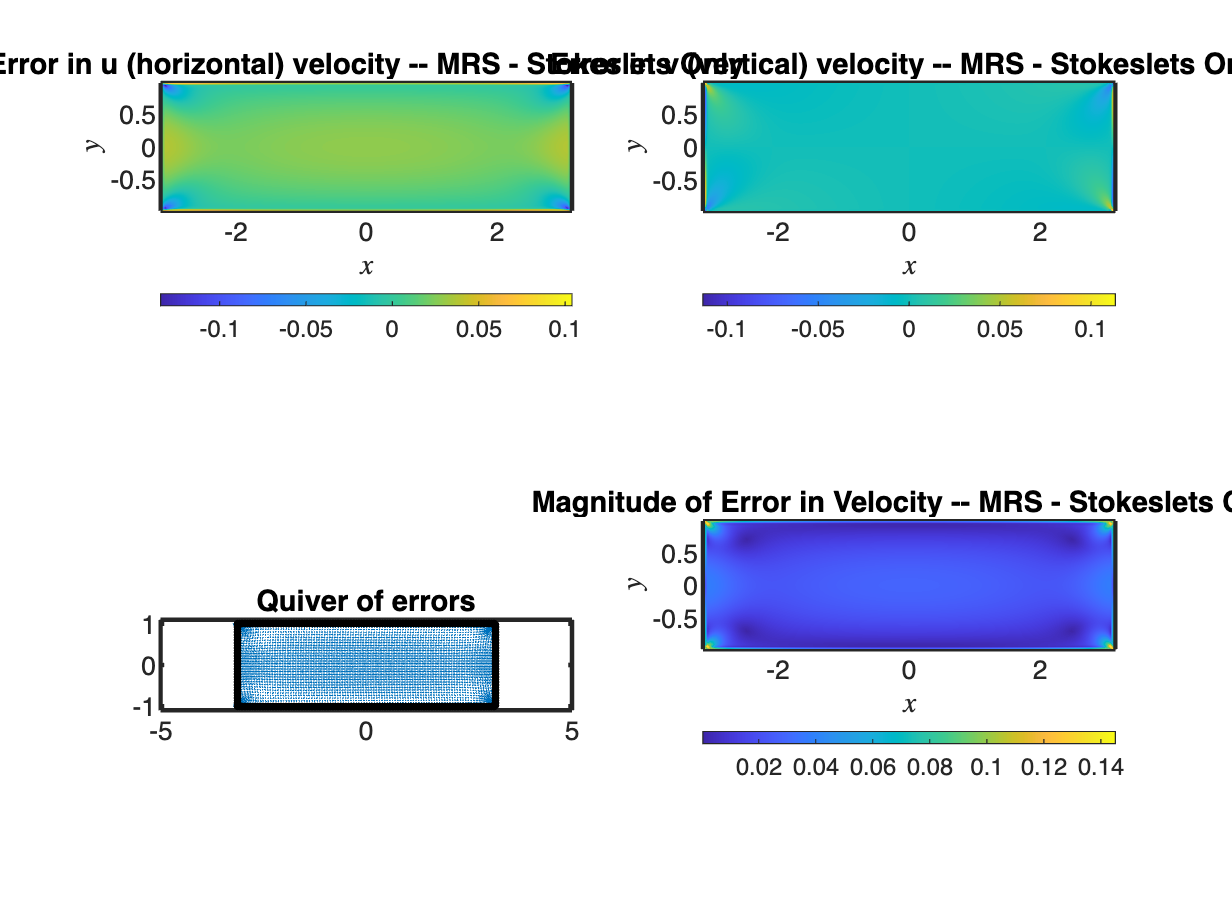

ans = 2×3 table
       Max            L1            L2    
    __________    __________    __________

    1.3415e-01    9.2900e-02    5.0999e-02
    1.1343e-01    1.7376e-02    1.8893e-02


% get exact solution everywhere
u_error = uexact - u1m';
v_error = vexact - u2m';

calculate_errors(u_error,v_error,xx1,xx2,dx_g,dy_g,y1,y2,'MRS - Stokeslets Only')

## Permeable wall computation with extended boundary (Stokeslets Only)

clear
close all 

#### **Set parameters**

- Blob choice 2 uses $\psi$ from 2021 paper

- Blob choice 1 uses $\phi$ from 2021 paper

%set Darcy number
Da = 0.4;
%viscosity
mu = 1; 
%choose blob
blob_num = 2;
% scale factor for epsilon*ds_y
epsilon_factor = 1; % sqrt(5)/2

% Number of source and target points
N = 160; % Number of source points (along top  and bottom boundaries)
Nx2 = 80; % Number of target points in y direction for full channel calc
Nx1 = floor(pi*Nx2); % Number of target points in x direction for full channel calc

#### **Define geometry and regularization**

% Setting forces and computing velocity 
% Channel geometry
Lx = pi;
Ly = 1;
xmin = -Lx;
xmax = Lx;
ymin = -Ly;
ymax = Ly;
xmin_ext = -3*Lx/2;
xmax_ext = 3*Lx/2;

scalefactor = 0.05; % for the boundary velocity figures (why?)

% Discretization step
ds_x = (xmax - xmin)/N;
ds_y = (ymax - ymin)/( ceil((ymax - ymin)/ds_x));

%regularization parameter
ep = epsilon_factor*ds_y;

#### **Discretization**

tb = top/bottom

lr = left/right

source point coordinates organized stacked:

    [top; bottom; left; right]

%discretization step of top/bottom walls
stb = xmin+ds_x/2:ds_x:xmax-ds_x/2;
stb = stb';
s_ext = [xmin_ext:ds_x:xmin-ds_x/2, xmax+ds_x/2:ds_x:xmax_ext]; % extended walls
s_ext = s_ext';
%discretization step of left/right wall (inlet/outlet)
slr = ymin+ds_y/2:ds_y:ymax-ds_y/2;
slr = slr';

% Define coordinates on each wall (x-coord,y-coord) (source points)
y1_top = [stb;s_ext];   y2_top = ymax*ones(size([stb;s_ext])); % top wall coordinates (y1_top,y2_top)
y1_bot = [stb;s_ext];   y2_bot = ymin*ones(size([stb;s_ext])); % bottom wall coordinates (y1_bot,y2_bot)
y1_left = xmin*ones(size(slr));   y2_left = slr; % left wall coordinates (y1_left,y2_left)
y1_right = xmax*ones(size(slr));   y2_right = slr; % right wall coordinates (y1_right,y2_right)
y1 = [y1_top; y1_bot; y1_left; y1_right]; %x-coordinates of all boundary points
y2 = [y2_top; y2_bot; y2_left; y2_right]; %y-coordinates of all boundary points

% Points where velocity will be computed within the channel (target points)
%xx1 = linspace(xmin+ds_x/2,xmax-ds_x/2,Nx1);
%xx2 = linspace(ymin+ds_y/2,ymax-ds_y/2,Nx2);
%xx1 = linspace(xmin,xmax,Nx1);
%xx2 = linspace(ymin,ymax,Nx2);
xx1 = stb';
xx2 = slr';
[x1m, x2m] = ndgrid(xx1, xx2);
x1 = x1m(:); %x-coords of points where computing velocity
x2 = x2m(:); %y-coords of points where computing velocity
dx_g = (xx1(end)-xx1(1))/Nx1;
dy_g = (xx2(end)-xx2(1))/Nx2;

#### **Set boundary velocities and beta**

% Define quadrature weights cooresponding to wall coordinates.
% Currently using midpoint rule.
wt = [ds_x*ones(size(y1_top)); ds_x*ones(size(y1_bot)); ds_y*ones(size(y1_left)); ds_y*ones(size(y1_right))];

% Exact velocities on boundaries using true solution (Bernardi, 2023)
[u1_top_exact,u2_top_exact,p_top_exact] = permeablechannelexact(y1_top,y2_top,Da); %top velocity
[u1_bot_exact,u2_bot_exact,p_bot_exact] = permeablechannelexact(y1_bot,y2_bot,Da); %bottom velocity
[u1_left_exact,u2_left_exact,p_left_exact] = permeablechannelexact(y1_left,y2_left,Da); % left velocity
[u1_right_exact,u2_right_exact,p_right_exact] = permeablechannelexact(y1_right,y2_right,Da); %right velocity

u1_bd_exact = [u1_top_exact; u1_bot_exact; u1_left_exact; u1_right_exact]; %x-coordinates of all boundary velocities
u2_bd_exact  = [u2_top_exact; u2_bot_exact; u2_left_exact; u2_right_exact]; %y-coordinates of all boundary velocities
p_bd_exact = [p_top_exact; p_bot_exact; p_left_exact; p_right_exact]; % pressure on boundary

u1_tb_exact = [u1_top_exact; u1_bot_exact];
u2_tb_exact = [u2_top_exact; u2_bot_exact];
p_tb_exact = [p_top_exact; p_bot_exact];

#### **Find forces on boundary due to known velocities**

% All four sides of channel
ftemp = RegStokeslets2D_velocitytoforce_KK([y1,y2], [y1,y2], [u1_bd_exact,u2_bd_exact], ep, mu, blob_num,wt);

log10 of condition number of Mat: 3.6707
condition number of Mat+D: 4685.2661
size of Mat+D: 1164  1164


#### **Compute velocity and pressure everywhere due to boundary forces**

ug = RegStokeslets2D_forcetovelocity([y1,y2],ftemp,[x1,x2],ep,mu,blob_num,wt);
ug1 = ug(:,1);
ug2 = ug(:,2);
u1m = reshape(ug1,size(xx1,2),size(xx2,2)); % x-coords of computed velocities everywhere
u2m = reshape(ug2,size(xx1,2),size(xx2,2)); % y-coords of computed velocities everywhere
ummag = sqrt(u1m.^2 + u2m.^2);

% computed pressure
p = RegStokeslets2D_forcetopressure([y1, y2], ftemp, [x1, x2], ep, mu, blob_num, wt);
pm = reshape(p,size(xx1,2),size(xx2,2));

### Plotting

#### Streamlines of Exact and Computed 

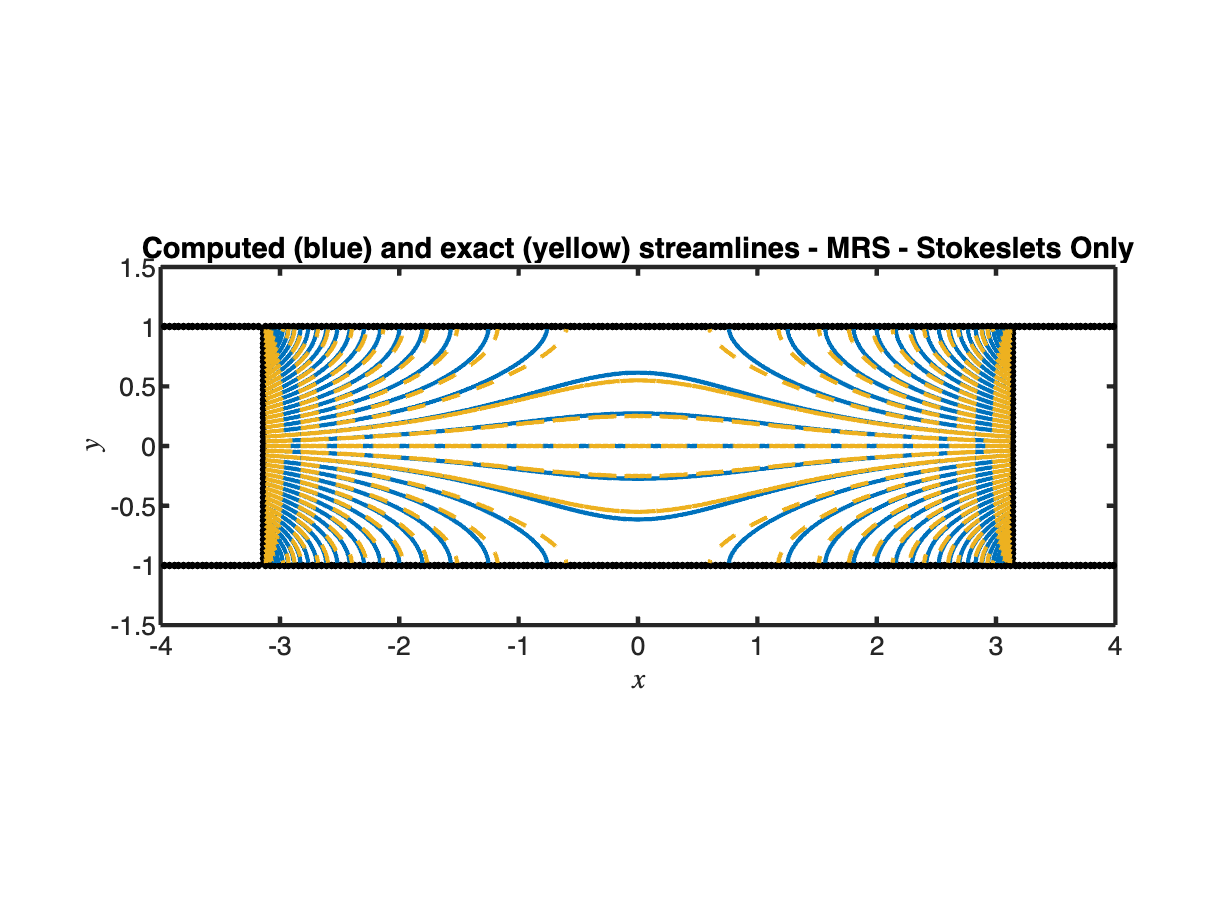

[x1gg, x2gg] = meshgrid(xx1, xx2);
[uexact,vexact,~] = permeablechannelexact(x1gg,x2gg,Da);
speed_exact = sqrt(uexact.^2 + vexact.^2);


figure
plot_streamline(u1m,u2m,x1gg,x2gg,uexact,vexact,y1,y2,'MRS - Stokeslets Only')

#### Quiver plot of exact velocities on boundaries

subplot(2,1,1)
plot_boundary_quiver(y1, y2, x1m, x2m, u1_bd_exact, u2_bd_exact, u1m, u2m)

#### pcolor plot of velocities everywhere with quiver of computed forces on boundaries

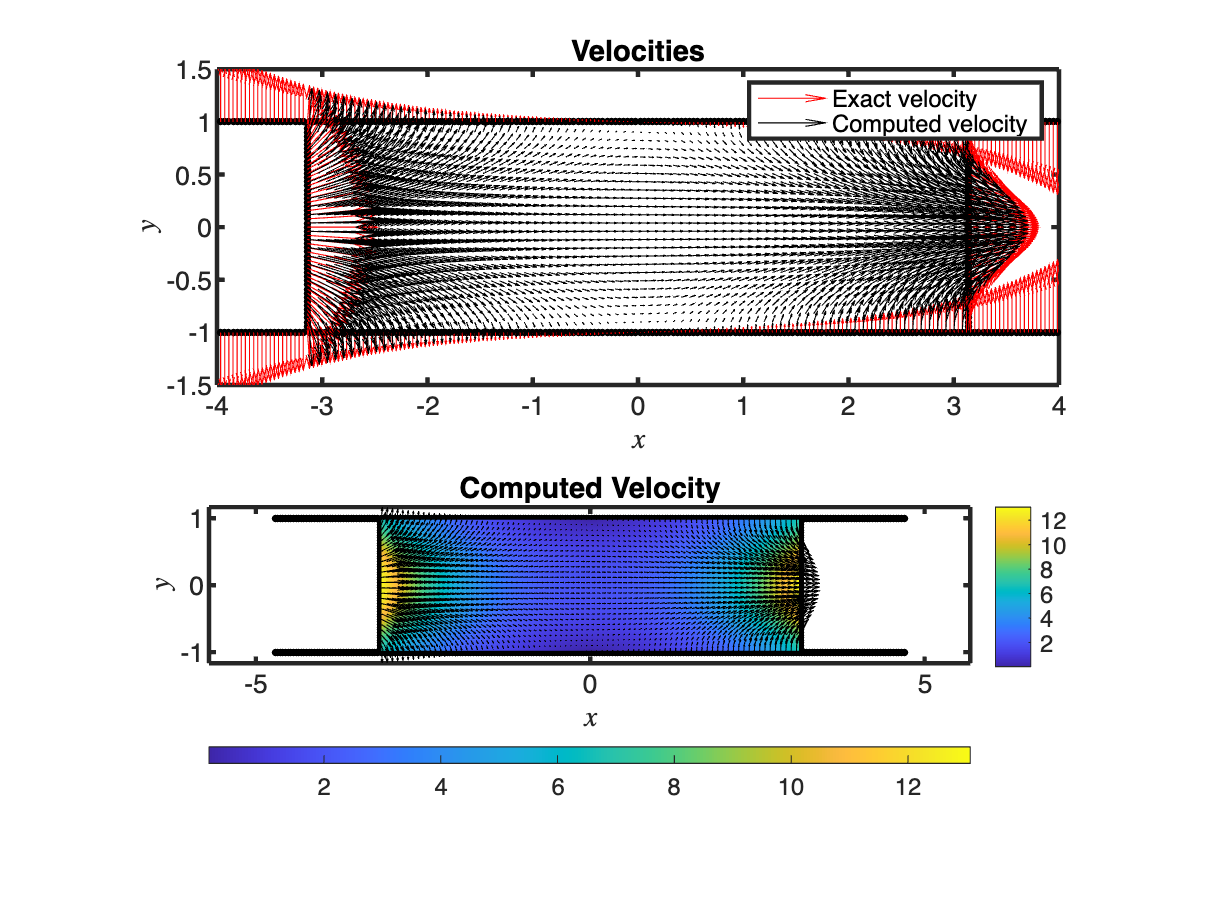

subplot(2,1,2)
plot_velocity_pcolor(y1,y2,x1m,x2m,u1m,u2m,ummag)

#### Calculate Errors and Plot

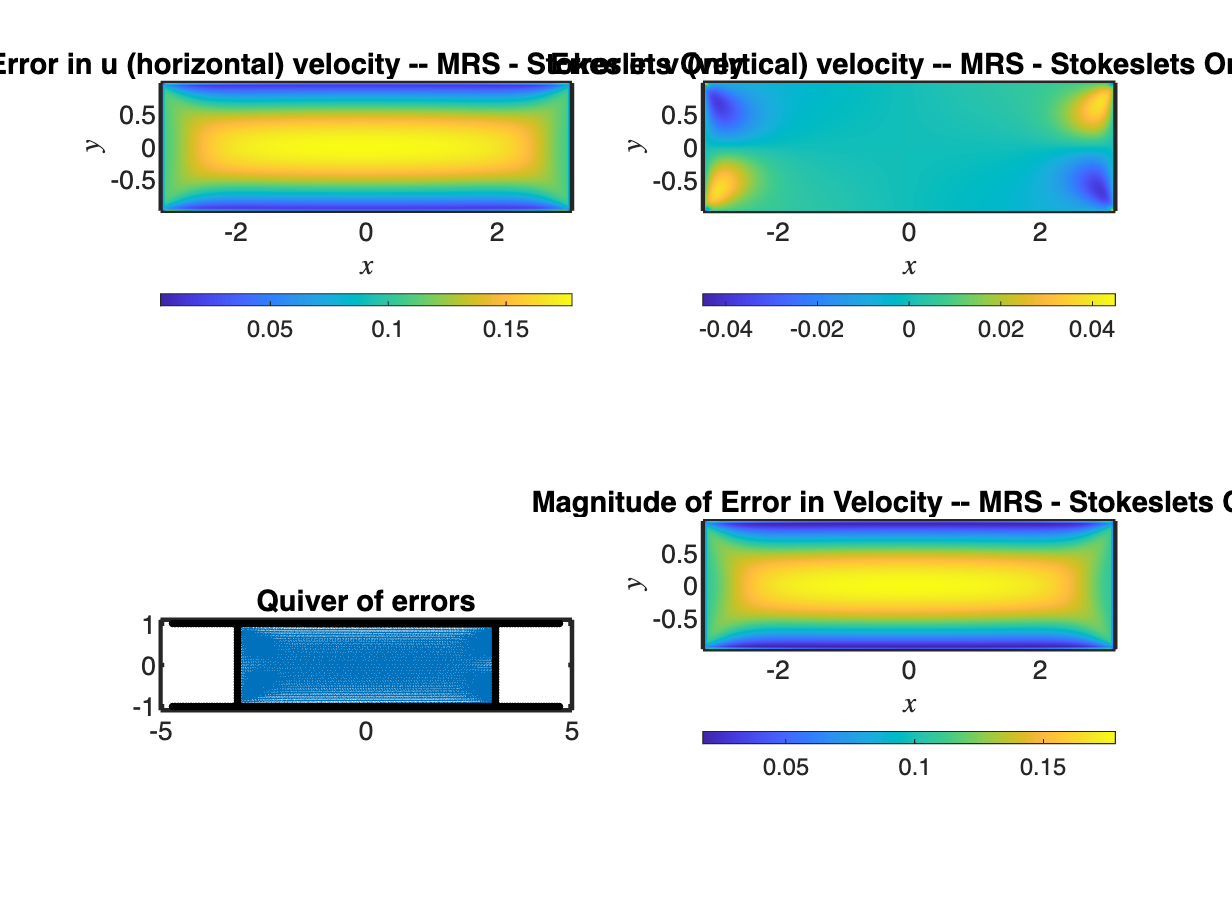

ans = 2×3 table
       Max            L1            L2    
    __________    __________    __________

    1.7792e-01    5.7076e-01    2.7532e-01
    4.4999e-02    3.1697e-02    2.3770e-02


% get exact solution everywhere
u_error = uexact - u1m';
v_error = vexact - u2m';

calculate_errors(u_error,v_error,xx1,xx2,dx_g,dy_g,y1,y2,'MRS - Stokeslets Only')

## Internal functions to be used by notebook

### **Exact Solution from FB paper**

function [ug,vg,pg] = permeablechannelexact(x,y,Da)

% Newton's method to find lambda1
L1=sqrt(2*Da);
f=@(L) tan(L)^2-tan(L)/L+1-2*Da;
L1 = fzero(f,L1);
%disp(['lambda_1 = ',num2str(L1)])

% Compute g and g' from FB paper
g  = cot(L1)*(Da-0.5)   *sin(L1*y)+0.5*y.*cos(L1*y);
gp = cot(L1)*(Da-0.5)*L1*cos(L1*y)+0.5*cos(L1*y)-0.5*L1*y.*sin(L1*y);

% Compute exact solution using g and g'
C = -4;   
pg = C*sinh(L1*x) .* cos(L1*y);
ug = -C/L1 * cosh(L1*x) .* gp;
vg =  C    * sinh(L1*x) .* g ;

end

### **Error Calculation**

%% Errors
function [errors] = calculate_errors(u_error,v_error,xx1,xx2,dx,dy,y1,y2,method_name)

scalefactor = 3;
skip = 1;

u_error_max = max(max(abs(u_error)));
v_error_max = max(max(abs(v_error)));
u_error_L1 = dx*dy*sum(sum(abs(u_error)));
v_error_L1 = dx*dy*sum(sum(abs(v_error)));
u_error_L2 = sqrt(dx*dy*sum(sum(u_error.^2)));
v_error_L2 = sqrt(dx*dy*sum(sum(v_error.^2)));
error_mag = sqrt(u_error.^2 + v_error.^2);

ColNames = {'Max','L1','L2'};
Emax = [u_error_max; v_error_max];
EL1 = [u_error_L1; v_error_L1];
EL2 = [u_error_L2; v_error_L2];
errors = table(Emax, EL1, EL2,'VariableNames',ColNames);

figure
subplot(2,2,1);
pcolor(xx1, xx2, u_error)
shading interp
colorbar('southoutside')
title(['Error in u (horizontal) velocity -- ' method_name]);
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal;
set(gca,'FontSize',12)

subplot(2,2,2);
pcolor(xx1, xx2, v_error)
shading interp
colorbar('southoutside')
title(['Error in v (vertical) velocity -- ' method_name]);
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal;
set(gca,'FontSize',12)

subplot(2,2,3);
quiver(xx1(1:skip:end,1:skip:end), xx2(1:skip:end,1:skip:end), u_error(1:skip:end,1:skip:end), v_error(1:skip:end,1:skip:end),scalefactor)
hold on
plot(y1,y2,'.k')
axis equal
ylim([-1.1,1.1])
xlim([-5,5])
title('Quiver of errors')
set(gca,'FontSize',12)

subplot(2,2,4);
pcolor(xx1, xx2, error_mag)
shading interp
colorbar('southoutside')
title(['Magnitude of Error in Velocity -- ' method_name]);
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal;
set(gca,'FontSize',12)

end

### **Generate Streamline Plots**

%% Streamline Plot function
function plot_streamline(u1m,u2m,x1gg,x2gg,uexact,vexact,y1,y2,method_name)

plot(y1, y2, 'k.')
hold on

% Computed streamlines
hh1_comp = streamline(x1gg, x2gg, u1m', u2m', x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_comp = streamline(x1gg, x2gg, -u1m', -u2m', x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall
% Exact streamlines
hh1_exact = streamline(x1gg, x2gg, uexact, vexact, x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_exact = streamline(x1gg, x2gg, -uexact, -vexact, x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall

strmLW = 2;
RGB = orderedcolors("gem");
set(hh1_comp, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh2_comp, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh1_exact, 'Color', RGB(3,:), 'LineStyle','--', 'linewidth', strmLW);
set(hh2_exact, 'Color', RGB(3,:), 'LineStyle','--', 'linewidth', strmLW);

title(['Computed (blue) and exact (yellow) streamlines - ' method_name])
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
axis([-4,4,-1.5,1.5])
set(gca,'FontSize',12)

end

### **Generate Quiver Plots on Boundaries**

%% Streamline Plot function
function plot_boundary_quiver(y1, y2, x1m, x2m, u1_exact, u2_exact, u1m, u2m)
skip = 2;
scalefactor = 0.05;

plot(y1,y2,'k.')
hold on
quiver(y1,y2,u1_exact*scalefactor,u2_exact*scalefactor,'r','AutoScale','off')
hold on
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m(1:skip:end,1:skip:end)*scalefactor,u2m(1:skip:end,1:skip:end)*scalefactor,'k','AutoScale','off')

title('Velocities')
legend('','Exact velocity', 'Computed velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
axis([-4,4,-1.5,1.5])
set(gca,'FontSize',12)
end


### **Quiver plot with pcolor velocity**

function plot_velocity_pcolor(y1,y2,x1m,x2m,u1m,u2m,ummag)
skip = 2;
scalefactor = 1.5;

plot(y1,y2,'k.')
hold on
pcolor(x1m,x2m,ummag)
shading interp
colorbar('southoutside')
set(gca,'FontSize',12)

axis equal
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m(1:skip:end,1:skip:end),u2m(1:skip:end,1:skip:end),scalefactor,'k','AutoScale','off')
colorbar
title('Computed Velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca,'FontSize',12)
end